 
clear
clc
tic
marketData = MarketData;
marketData = marketData.loadSymbolMCapRef;
toc
%----------------------------------------------------------------------------------------


 
tic
marketData = marketData.loadDataFromYahoo
toc

 
tic
marketData = marketData.loadDataFromSpreadsheet;
toc


 
tic
marketData = marketData.loadDataFromMatFile;
toc
%----------------------------------------------------------------------------------------


 
tic
marketData = marketData.cleanData;
toc
%----------------------------------------------------------------------------------------


 
tic
marketData.saveDataToSpreadsheet;
toc
%----------------------------------------------------------------------------------------


 
tic
marketData.saveDataToMatFile;
toc
%----------------------------------------------------------------------------------------


 
% prepare the data
marketData

marketData =   MarketData with properties:

                     yahooData_path: "C:\Users\kikim\OneDrive\Documents\MATLAB_Projects\BackTradeModule_Project_WFA_Feature_Development\DataInput"
                 yahooData_fileName: "Symbols_MarketCap_MarketCapCategoryRange.xlsx"
       yahooData_symMktCapSheetName: "SymbolsMarketCapReference"
    yahooData_mktCapCategRangeSheet: "MarketCap_Category_Range"
                          startDate: 01-Jan-2014
                            endDate: 20-Feb-2022
                           interval: "1d"
                           maxRetry: 3
           spreadhseetData_filename: "PriceVolumeInput.xlsx"
               spreadhseetData_path: "C:\Users\kikim\OneDrive\Documents\MATLAB_Projects\BackTradeModule_Project_WFA_Feature_Development\DataInput"
     spreadhseetData_openPriceSheet: "openPrice"
      spreadhseetData_lowPriceSheet: "lowPrice"
     spreadhseetData_highPriceSheet: "highPr


dataInput.openPrice = marketData.openPrice;
dataInput.highPrice = marketData.highPrice;
dataInput.lowPrice = marketData.lowPrice;
dataInput.closePrice = marketData.closePrice;
dataInput.volume = marketData.volume;
%----------------------------------------------------------------------------------------


 
tic
% generate tradingSignal
tradingSignalParameter =[               % open the array
                            0        % liquidityVolumeMALookback = paramInput(1);
                            0.1        % liquidityVolumeMAThreshold = paramInput(2);
                            3       %liquidityVolumeMANDayBuffer = paramInput(3) 
                            0        % liquidityValueMALookback  = paramInput(4);
                            0.1        % liquidityValueeMAThreshold  = paramInput(5);
                            3       %liquidityValueMANDayBuffer = paramInput(6)
                            20        % liquidityNDayVolumeValueBuffer = paramInput(7);
                            20        % momentumPriceMALookback = paramInput(8);
                            1.2        % momentumPriceMAToCloseThreshold = paramInput(9);
                            1        % momentumPriceRetLowToCloseLookback = paramInput(10);
                            0.05        % momentumPriceRetLowToCloseThreshold = paramInput(11);
                            3        % momentumPriceRetLowToCloseNDayBuffer = paramInput(12);
                            5        % liquidityMomentumSignalBuffer = paramInput(13);
                            5        % cutLossHighToCloseNDayLookback = paramInput(14);
                            0.05        % cutLossHighToCloseMaxPct = paramInput(15);
                                ] ;  % close the array


tradingSignalOut = generateTradingSignalFcn (dataInput, tradingSignalParameter)

tradingSignalOut = 2031×709 timetable
       Time       AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    <s

toc

Elapsed time is 0.873313 seconds.


%----------------------------------------------------------------------------------------


 
% backtest the signal

tic
dataStructInput = dataInput;
tradingSignal = tradingSignalOut;
tradingCost = [0.15/100, 0.25/100];
maxCapAllocation = 0.2;

resultStruct = btEngineVectorizedFcn (dataStructInput, tradingSignal, tradingCost, maxCapAllocation)

resultStruct = struct with fields:
    dailyNetRetPortfolioTT: [2031×1 timetable]
    equityCurvePortfolioTT: [2031×1 timetable]
       dailyNetRetPerSymTT: [2031×709 timetable]
       equityCurvePerSymTT: [2031×709 timetable]
              totalBuyCost: 0.2365
             totalSellCost: 0.3914
         totalSlippageCost: -4.7891


toc

Elapsed time is 1.613851 seconds.


%----------------------------------------------------------------------------------------


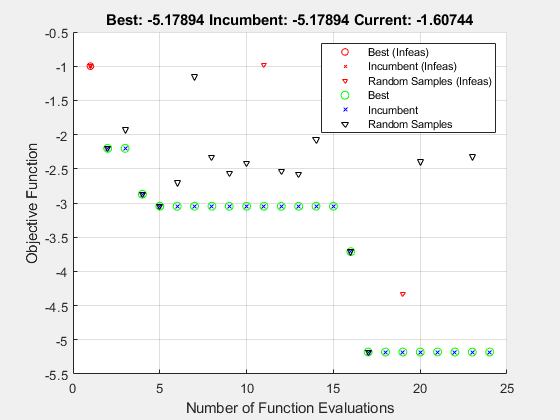

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimStructOut = struct with fields:
    optimizedTradingSignalParam: [118 234 211 180 266 149 211 118 78 24 203 164 164 86 16 195.5312]
                           fval: -5.1789
                       exitflag: 0
                         output: [1×1 struct]


 
% optimize the parameter
dataStructInput = dataInput;
tradingCost = [0.15/100, 0.25/100];
maxCapAllocation = 0.2;
optimLookbackStep = 250*7;
maxDDThreshold = -0.50;
minPortfolioReturn = 1.10;
minDailyRetThreshold = -0.20;
maxFcnEval = 24;

optimStructOut = optimParamsFcn (dataStructInput, optimLookbackStep, tradingCost,...
                 maxCapAllocation, maxDDThreshold, minPortfolioReturn,...

                 minDailyRetThreshold, maxFcnEval)

tOptimParam = toc

tOptimParam = 86.1113

%----------------------------------------------------------------------------------------

% check the optimized parameters
 
tic

% generate tradingSignal
% tradingSignalParameter =[               % open the array
%                             0        % liquidityVolumeMALookback = paramInput(1);
%                             0.1        % liquidityVolumeMAThreshold = paramInput(2);
%                             3       %liquidityVolumeMANDayBuffer = paramInput(3) 
%                             0        % liquidityValueMALookback  = paramInput(4);
%                             0.1        % liquidityValueeMAThreshold  = paramInput(5);
%                             3       %liquidityValueMANDayBuffer = paramInput(6)
%                             20        % liquidityNDayVolumeValueBuffer = paramInput(7);
%                             20        % momentumPriceMALookback = paramInput(8);
%                             1.2        % momentumPriceMAToCloseThreshold = paramInput(9);
%                             1        % momentumPriceRetLowToCloseLookback = paramInput(10);
%                             0.05        % momentumPriceRetLowToCloseThreshold = paramInput(11);
%                             3        % momentumPriceRetLowToCloseNDayBuffer = paramInput(12);
%                             5        % liquidityMomentumSignalBuffer = paramInput(13);
%                             5        % cutLossHighToCloseNDayLookback = paramInput(14);
%                             0.05        % cutLossHighToCloseMaxPct = paramInput(15);
%                             1        % nDayBackShift = paramInput(16);
%                                 ] ;  % close the array

% transfer the data
dataInput;
tradingSignalParameter = structOut.optimParams;

tradingSignalOut = generateTradingSignalFcn (dataInput, tradingSignalParameter)

tradingSignalOut = 2031×709 timetable
       Time       AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    <s

toc

Elapsed time is 0.529479 seconds.


%----------------------------------------------------------------------------------------


% backtest the signal

tic
dataStructInput = dataInput;
tradingSignal = tradingSignalOut;
tradingCost = [0.15/100, 0.25/100];
maxCapAllocation = 0.2;

resultStruct = btEngineVectorizedFcn (dataStructInput, tradingSignal, tradingCost, maxCapAllocation)

resultStruct = struct with fields:
    dailyNetRetPortfolioTT: [2031×1 timetable]
    equityCurvePortfolioTT: [2031×1 timetable]
       dailyNetRetPerSymTT: [2031×709 timetable]
       equityCurvePerSymTT: [2031×709 timetable]
              totalBuyCost: 0.1064
             totalSellCost: 0.1809
         totalSlippageCost: -0.0168



% check the results
equityCurvePortfolio = resultStruct.equityCurvePortfolioTT.Variables;
maxDD = maxdrawdown(equityCurvePortfolio)

maxDD = 0.2044


endPortValue = equityCurvePortfolio(end,:)

endPortValue = 5.1789

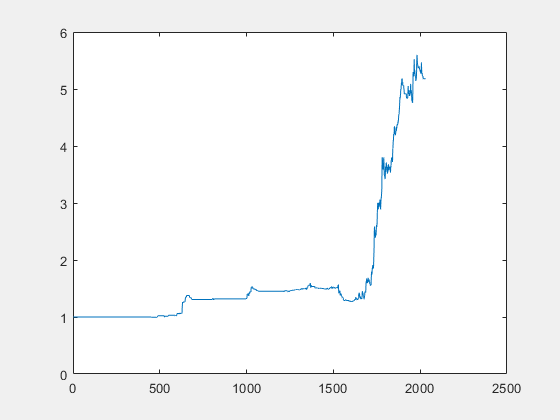

plot(equityCurvePortfolio)

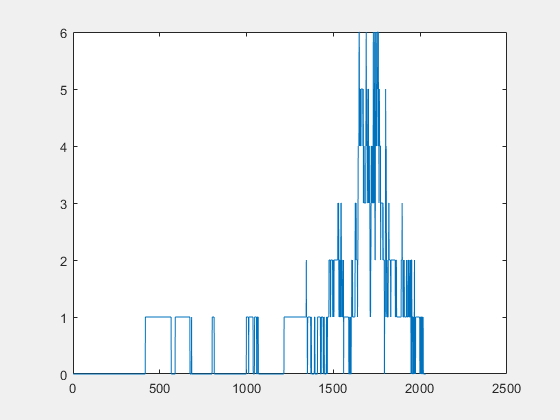

plot(sum(tradingSignalOut.Variables,2))

toc

Elapsed time is 4.217891 seconds.




%----------------------------------------------------------------------------------------


% walk forwad set up

%----------------------------------------------------------------------------------------


% do walk forwad

% analyze the result
% equityCurveTT = resultStruct.equityCurvePortfolioTT.Variables;
% plot(resultStruct.equityCurvePortfolioTT.Variables);
% cumRet = equityCurveTT (end) / equityCurveTT (1) -1
% maxDD = maxdrawdown(equityCurveTT)


% data for generateTradingSignalFcn 

